clc
clear all

**Задание 1. Гистограммы. **

Выбрать произвольное слабоконтрастное изображение. Выполнить выравнивание гистограммы и растяжение контраста, использовать рассмотренные преобразования и встроенные функции пакета MATLAB. Сравнить полученные результаты. 

Считаем изображение и конвертируем его в оттенки серого

img = imread('spb2.jpg');   % Загрузка изображения
gray = rgb2gray(img);       % Преобразование в оттенки серого
[numRows, numCols, Layers] = size(gray);

Выведем изображения и их гистограммы, для цветного случая выведем 3 гистограммы

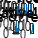


figure;
% Изначальное изображение
subplot(2,4,1);
imshow(img);
title('Оригинальное изображение');

subplot(2,4,5);
imshow(gray);
title('Изображение в оттенках серого');

% Построим гистограммы
subplot(2,4,6);
imhist(gray);
title('Гистограмма изображения в оттенках серого');

subplot(2,4,2);
imhist(img(:, :, 1));
title('Red histogram');

subplot(2,4,3);
imhist(img(:, :, 2));
title('Green histogram');

subplot(2,4,4);
imhist(img(:, :, 3));
title('Blue histogram');

% добавим кумулятивную гистограмму
cum_hist = cumsum(imhist(gray)) ./ (numRows * numCols);

subplot(2,4,8);
plot(cum_hist);
title('Cumulative histogram');

Арифметические операции

Ishift = gray + 50;

figure;

subplot(2,3,1);
imshow(gray);

subplot(2,3,4);
imshow(Ishift);

subplot(2,3,2);
imhist(gray);
title('Histogram before');

subplot(2,3,5);
imhist(Ishift);
title('Histogram after');

subplot(2,3,3);
plot(cumsum(imhist(gray)) ./ (numRows * numCols));
title('Cumulative Histogram before');

subplot(2,3,6);
plot(cumsum(imhist(Ishift)) ./ (numRows * numCols));
title('Cumulative Histogram after');

Нелинейное растяжение динамического диапазона

% Коэффициент растяжения
alfa = 0.8;

% Calculate minimum and maximum image intensity values
Imin = min(min(gray));
Imax = max(max(gray));

% Apply formula
Inew = ((double( gray - Imin ) ./ double( Imax - Imin ))) .^ alfa;

% Let's also show histograms before and after to compare
figure;

subplot(2,3,1);
imshow(gray);

subplot(2,3,4);
imshow(Inew);

subplot(2,3,2);
imhist(gray);
title('Histogram before');

subplot(2,3,5);
imhist(Inew);
title('Histogram after');

subplot(2,3,3);
plot(cumsum(imhist(gray)) ./ (numRows * numCols));
title('Cumulative Histogram before');

subplot(2,3,6);
plot(cumsum(imhist(Inew)) ./ (numRows * numCols));
title('Cumulative Histogram after');

Равномерное преобразование

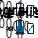

Imin = double(Imin / 255);
Imax = double(Imax / 255);
for i = 1:1: numRows;
    for j = 1:1: numCols;
        index = gray(i,j);
        if index == 0;
            index = 1;
        end
        Inew(i,j) = (Imax - Imin) * cum_hist(index) + Imin;
    end
end

% Let's also show histograms before and after to compare
figure;

subplot(2,3,1);
imshow(gray);

subplot(2,3,4);
imshow(Inew);

subplot(2,3,2);
imhist(gray);
title('Histogram before');

subplot(2,3,5);
imhist(Inew);
title('Histogram after');

subplot(2,3,3);
plot(cumsum(imhist(gray)) ./ (numRows * numCols));
title('Cumulative Histogram before');

subplot(2,3,6);
plot(cumsum(imhist(Inew)) ./ (numRows * numCols));
title('Cumulative Histogram after');

Экспоненциальное преобразование

gamma = 1.5; % Параметр экспоненциального преобразования
Inew = double(gray).^gamma;
Inew = uint8(255 * mat2gray(Inew)); % Нормализация

figure;
subplot(2,3,1);
imshow(gray);
title('Оригинальное изображение');

subplot(2,3,4);
imshow(Inew);
title('Экспоненциальное преобразование');

subplot(2,3,2);
imhist(gray);
title('Histogram before');

subplot(2,3,5);
imhist(Inew);
title('Histogram after');

subplot(2,3,3);
plot(cumsum(imhist(gray)) ./ (numRows * numCols));
title('Cumulative Histogram before');

subplot(2,3,6);
plot(cumsum(imhist(Inew)) ./ (numRows * numCols));
title('Cumulative Histogram after');

Преобразование Рэлея

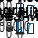

a = 50; % Коэффициент масштабирования
Inew = uint8(a * sqrt(-2 * log(1 - double(gray) / 255)));

figure;
subplot(2,3,1);
imshow(gray);
title('Оригинальное изображение');

subplot(2,3,4);
imshow(Inew);
title('Преобразование Рэлея');

subplot(2,3,2);
imhist(gray);
title('Histogram before');

subplot(2,3,5);
imhist(Inew);
title('Histogram after');

subplot(2,3,3);
plot(cumsum(imhist(gray)) ./ (numRows * numCols));
title('Cumulative Histogram before');

subplot(2,3,6);
plot(cumsum(imhist(Inew)) ./ (numRows * numCols));
title('Cumulative Histogram after');

Преобразование 2/3 степени

Inew = double(gray) .^ (2/3);
Inew = uint8(255 * mat2gray(Inew));

figure;
subplot(2,3,1);
imshow(gray);
title('Оригинальное изображение');

subplot(2,3,4);
imshow(Inew);
title('Преобразование 2/3 степени');

subplot(2,3,2);
imhist(gray);
title('Histogram before');

subplot(2,3,5);
imhist(Inew);
title('Histogram after');

subplot(2,3,3);
plot(cumsum(imhist(gray)) ./ (numRows * numCols));
title('Cumulative Histogram before');

subplot(2,3,6);
plot(cumsum(imhist(Inew)) ./ (numRows * numCols));
title('Cumulative Histogram after');

Гиперболическое преобразование

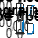

c = 255 / log(1 + double(max(gray(:)))); % Нормировочный коэффициент
Inew = uint8(c * log(1 + double(gray)));

figure;
subplot(2,3,1);
imshow(gray);
title('Оригинальное изображение');

subplot(2,3,4);
imshow(Inew);
title('Гиперболическое преобразование');

subplot(2,3,2);
imhist(gray);
title('Histogram before');

subplot(2,3,5);
imhist(Inew);
title('Histogram after');

subplot(2,3,3);
plot(cumsum(imhist(gray)) ./ (numRows * numCols));
title('Cumulative Histogram before');

subplot(2,3,6);
plot(cumsum(imhist(Inew)) ./ (numRows * numCols));
title('Cumulative Histogram after');

Встроенные преобразования MATLAB

Выравнивание histeq

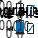

% Выравнивание 1
Inew = histeq(gray);
figure

subplot(2,3,1);
imshow(gray);

subplot(2,3,4);
imshow(Inew);

subplot(2,3,2);
imhist(gray);
title('Histogram before');

subplot(2,3,5);
imhist(Inew);
title('Histogram after');

subplot(2,3,3);
plot(cumsum(imhist(gray)) ./ (numRows * numCols));
title('Cumulative Histogram before');

subplot(2,3,6);
plot(cumsum(imhist(Inew)) ./ (numRows * numCols));
title('Cumulative Histogram after');

Выравнивание imadjust

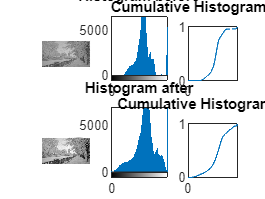

% Выравнивание 2
Inew = imadjust(gray,[0.2 0.8]);

figure

subplot(2,3,1);
imshow(gray);

subplot(2,3,4);
imshow(Inew);

subplot(2,3,2);
imhist(gray);
title('Histogram before');

subplot(2,3,5);
imhist(Inew);
title('Histogram after');

subplot(2,3,3);
plot(cumsum(imhist(gray)) ./ (numRows * numCols));
title('Cumulative Histogram before');

subplot(2,3,6);
plot(cumsum(imhist(Inew)) ./ (numRows * numCols));
title('Cumulative Histogram after');

Выравнивание adapthisteq

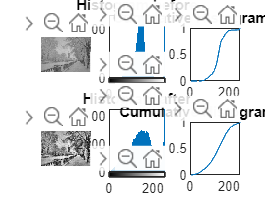

% Выравнивание 3
Inew = adapthisteq(gray);

figure

subplot(2,3,1);
imshow(gray);

subplot(2,3,4);
imshow(Inew);

subplot(2,3,2);
imhist(gray);
title('Histogram before');

subplot(2,3,5);
imhist(Inew);
title('Histogram after');

subplot(2,3,3);
plot(cumsum(imhist(gray)) ./ (numRows * numCols));
title('Cumulative Histogram before');

subplot(2,3,6);
plot(cumsum(imhist(Inew)) ./ (numRows * numCols));
title('Cumulative Histogram after');

**Задание 2. Профили. **

Выбрать произвольное изображение, содержащие штрих-код. Выполнить построение профиля изображения вдоль штрих-кода. 

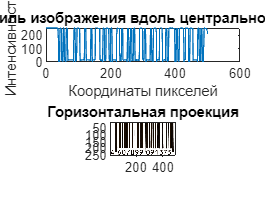

img2 = imread('штрихкод.jpg');
gray2 = rgb2gray(img2);
profile_line = gray2(round(end/2), :); % Выбираем центральную строку изображения

figure();
% График профиля
subplot(2,1,1);
plot(profile_line);
title('Профиль изображения вдоль центральной строки');
xlabel('Координаты пикселей');
ylabel('Интенсивность');

% Вывод изображения
subplot(2,1,2);
imshow(img2);
title('Горизонтальная проекция');
axis on; 

**Задание 3. Проекции. **

Выбрать произвольное изображение, содержащее монотонные области и выделяющиеся объекты. Произвести построение проекций изображения на вертикальную и горизонтальную оси. Определить границы областей объектов. 

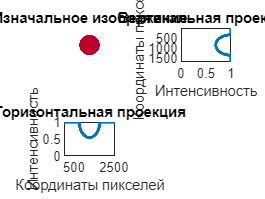

img3 = imread('Flag_of_Japan.jpg');
gray3 = rgb2gray(img3);

% Горизонтальная проекция
horizontal_projection = sum(gray3, 1);
horizontal_projection = horizontal_projection / max(horizontal_projection(:)); % Нормализация

% Вертикальная проекция
vertical_projection = sum(gray3, 2);
vertical_projection = vertical_projection / max(vertical_projection(:)); % Нормализация

figure;

% Изначальное изображение
subplot(2,2,1);
imshow(img3);
title('Изначальное изображение');

% Вертикальная проекция (переворачиваем ось Y)
subplot(2,2,2);
plot(vertical_projection, 1:size(gray3,1), 'LineWidth', 2);
set(gca, 'YDir', 'reverse'); % Инвертируем ось Y
xlim([0, 1]);
ylim([1, size(gray3,1)]);
title('Вертикальная проекция');
xlabel('Интенсивность');
ylabel('Координаты пикселей');

% Горизонтальная проекция
subplot(2,2,3);
plot(horizontal_projection, 'LineWidth', 2);
xlim([1, size(gray3,2)]);
ylim([0, 1]); 
title('Горизонтальная проекция');
ylabel('Интенсивность');
xlabel('Координаты пикселей');


% Поиск центра круга
for i = 2:length(horizontal_projection)
    if horizontal_projection(i) > horizontal_projection(i-1) % Проверяем, больше ли текущий элемент предыдущего
        maxValue = horizontal_projection(i); % Устанавливаем новое значение максимума
        position_x = i;     % Обновляем позицию
        break;           % Завершаем цикл
    end
end
for i = 2:length(vertical_projection)
    if vertical_projection(i) > vertical_projection(i-1) % Проверяем, больше ли текущий элемент предыдущего
        maxValue = vertical_projection(i); % Устанавливаем новое значение максимума
        position_y = i;     % Обновляем позицию
        break;           % Завершаем цикл
    end
end
position_x

position_x = 1283

position_y

position_y = 855